%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Cereated by Manishkumar Paghda , 12/01/24
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


clc
clear all
close all


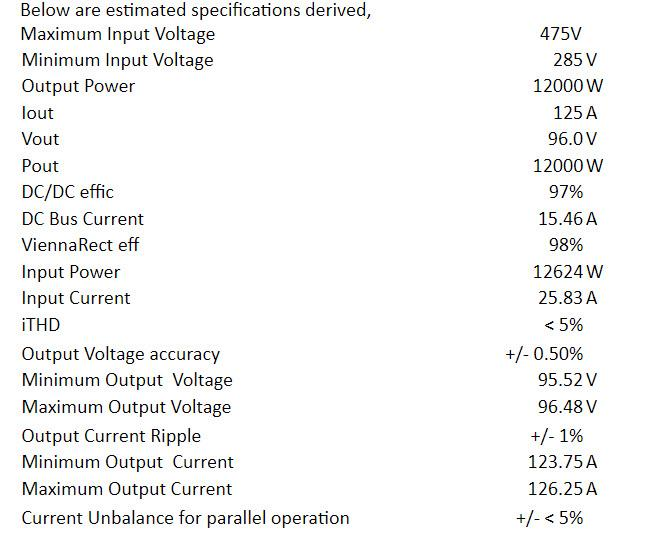

Tsim = 1e-7;

P_out =  12000; %watts

V_out_acdc = 750;
V_in_dcdc = V_out_acdc;
V_out_dcdc = 96;
Imax_out = 126.25*1.05;
Fs =  50000; %switching frequency
Tswitching = 1/Fs;

single_phase = 0;
Unbalance =   0;  %0: balanced 3 pha, 1: Unbalanced 3 ph
harmonics = 0;      % 0: No harmonics in grid, 1: 3rd and 5th harmonics in grid voltage
power_base_control = 2;  %0: current based control, 1:power based control , 2: power and sequence components based control
vdc_fbk_filter = 0;      %0: No notch filter on Vdc feedback
sogi_pr = 1;  %0: cur control PR is non SOGI based , 1: Cur control PR is SOGI based
sfunc_based_con = 0; %0: simlink block  based control, 1: s-function based control

%AC- DC converter design

    acdc.Pout =  12000;
    acdc.Vac_ll_rms = 400;
    acdc.Vph_rms =  acdc.Vac_ll_rms/sqrt(3);
    acdc.Fac = 50;
    acdc.Wac = acdc.Fac*2*pi;
    acdc.Tac = 1/acdc.Fac;
    acdc.Vout = 800;
    acdc.Iout = acdc.Pout/acdc.Vout;
    acdc.Eff = 0.97;
    acdc.Fs = 70000;
    acdc.Tsw = 1/acdc.Fs;
    acdc.Tcur_loop = acdc.Tsw*2;
    acdc.Tvolt_loop = acdc.Tcur_loop;
    acdc.Pin_max = acdc.Pout/acdc.Eff * 1.5;

    if(Unbalance == 0)

        acdc.va = acdc.Vac_ll_rms/sqrt(3);
        acdc.vb = acdc.Vac_ll_rms/sqrt(3);
        acdc.vc = acdc.Vac_ll_rms/sqrt(3);



        acdc.va_ph = 0; 
        acdc.vb_ph = -120; 
        acdc.vc_ph = 120; 

    else

        acdc.va = acdc.Vac_ll_rms/sqrt(3);
        acdc.vb = acdc.Vac_ll_rms/sqrt(3);
        acdc.vc = acdc.Vac_ll_rms/sqrt(3)*0.8;

        acdc.va_ph = 0; 
        acdc.vb_ph = -116; 
        acdc.vc_ph = 124; 

    end
   
        acdc.va_pk = acdc.va *sqrt(2);
        acdc.vb_pk = acdc.vb *sqrt(2);
        acdc.vc_pk = acdc.vc *sqrt(2);

        acdc.va_ph_rad = acdc.va_ph *pi/180;
        acdc.vb_ph_rad = acdc.vb_ph *pi/180;
        acdc.vc_ph_rad = acdc.vc_ph *pi/180;

        if(harmonics == 1)
            acdc.va_pk_3rd= acdc.va_pk *0.05;
            acdc.vb_pk_3rd= acdc.vb_pk *0.05;
            acdc.vc_pk_3rd= acdc.vc_pk *0.05;

            acdc.va_pk_5th= acdc.va_pk *0.03;
            acdc.vb_pk_5th= acdc.vb_pk *0.03;
            acdc.vc_pk_5th= acdc.vc_pk *0.03;

        else

            acdc.va_pk_3rd= 0;
            acdc.vb_pk_3rd= 0;
            acdc.vc_pk_3rd= 0;

            acdc.va_pk_5th= 0;
            acdc.vb_pk_5th= 0;
            acdc.vc_pk_5th= 0;

        end


    acdc.Pin = acdc.Pout/ acdc.Eff;
    acdc.Igrid_ph_pk = sqrt(2)*acdc.Pin/(sqrt(3)*acdc.Vac_ll_rms);
    acdc.cur_ripple = acdc.Igrid_ph_pk*0.05; %  1%

    acdc.L = acdc.Vout/(8*acdc.cur_ripple*acdc.Fs);
    acdc.L_ESR = 0.0468;

    X = (2*pi*50* acdc.L)

X = 0.3554


    acdc.Vripple = acdc.Vout*0.01; %1 %

%     acdc.C =1/3 *  acdc.Pout/(4*acdc.Fs * (acdc.Vout^2 - (acdc.Vout - acdc.Vripple )^2))
    acdc.C = (acdc.Iout*0.005)*0.98*acdc.Tac/acdc.Vripple

acdc = struct with fields:
           Pout: 12000
     Vac_ll_rms: 400
        Vph_rms: 230.9401
            Fac: 50
            Wac: 314.1593
            Tac: 0.0200
           Vout: 800
           Iout: 15
            Eff: 0.9700
             Fs: 70000
            Tsw: 1.4286e-05
      Tcur_loop: 2.8571e-05
     Tvolt_loop: 2.8571e-05
        Pin_max: 1.8557e+04
             va: 230.9401
             vb: 230.9401
             vc: 230.9401
          va_ph: 0
          vb_ph: -120
          vc_ph: 120
          va_pk: 326.5986
          vb_pk: 326.5986
          vc_pk: 326.5986
      va_ph_rad: 0
      vb_ph_rad: -2.0944
      vc_ph_rad: 2.0944
      va_pk_3rd: 0
      vb_pk_3rd: 0
      vc_pk_3rd: 0
      va_pk_5th: 0
      vb_pk_5th: 0
      vc_pk_5th: 0
            Pin: 1.2371e+04
    Igrid_ph_pk: 25.2525
     cur_ripple: 1.2626
              L: 0.0011
          L_ESR: 0.0468
        Vripple: 8
              C: 1.8375e-04


%     acdc.C = (acdc.Iout*0.01)*0.98*acdc.Tac/acdc.Vripple


    acdc.Vac_ph_rms =  acdc.Vac_ll_rms/sqrt(3); %rms
    acdc.Vac_ph_pk = acdc.Vac_ph_rms*sqrt(2);
    
    acdc.Vref = acdc.Vout;

    acdc.Rload = acdc.Vref ^2/acdc.Pout;
      
    Cur_loop_upper_limit_acdc = acdc.Vout/2;
    acdc.cur_con_sogi_k = 0.06366198;
    
    %PR controller

    acdc.cur_con_kp = 0.1*500 ;
    acdc.cur_con_ki = 0.6*500 ;

    wc = 10;
    wo = 2*pi*acdc.Fac;

    acdc.cur_con_sogi_k = 2*wc/(acdc.Wac);
    

%%%%%%% Current loop  gains %%%%%%%%%%%%%%%%%
kp_ff = 10^(29/20);
      kr_ff = 5;
      P_s = kp_ff*tf([0,1],[0,1])


P_s =
 
  28.18
 
Static gain.
Model Properties


      R_s = kr_ff*tf([2*wc,0],[1 2*wc wo^2])


R_s =
 
         100 s
  --------------------
  s^2 + 20 s + 9.87e04
 
Continuous-time transfer function.
Model Properties


      PR_s = P_s + R_s


PR_s =
 
  28.18 s^2 + 663.7 s + 2.782e06
  ------------------------------
       s^2 + 20 s + 9.87e04
 
Continuous-time transfer function.
Model Properties



      plant_s = tf([0,1],[acdc.L,acdc.L_ESR])


plant_s =
 
           1
  -------------------
  0.001131 s + 0.0468
 
Continuous-time transfer function.
Model Properties



%       acdc.Tcur_loop = 0.0001;
      s = tf('s');
      time_delay = acdc.Tcur_loop;
      sys = exp(-time_delay*s);    
      delay_s = pade(sys,1)


delay_s =
 
  -s + 70000
  ----------
  s + 70000
 
Continuous-time transfer function.
Model Properties


    OL_s = PR_s * plant_s *delay_s


OL_s =
 
       -28.18 s^3 + 1.972e06 s^2 + 4.368e07 s + 1.947e11
  -----------------------------------------------------------
  0.001131 s^4 + 79.27 s^3 + 4973 s^2 + 7.887e06 s + 3.233e08
 
Continuous-time transfer function.
Model Properties



    figure
    w_range = linspace(0.1,5000*2*pi,5000);
    h = bodeplot(OL_s,w_range);
    setoptions(h,'MagUnits','dB','FreqUnits','Hz','FreqScale','log')
%    

    plant_d = c2d(plant_s,acdc.Tcur_loop,'ZOH')


plant_d =
 
   0.02524
  ----------
  z - 0.9988
 
Sample time: 2.8571e-05 seconds
Discrete-time transfer function.
Model Properties


    PR_d = c2d(PR_s,acdc.Tcur_loop,'tustin')


PR_d =
 
  28.19 z^2 - 56.35 z + 28.17
  ---------------------------
    z^2 - 1.999 z + 0.9994
 
Sample time: 2.8571e-05 seconds
Discrete-time transfer function.
Model Properties


    OL_d = PR_d * plant_d


OL_d =
 
    0.7113 z^2 - 1.422 z + 0.7108
  ----------------------------------
  z^3 - 2.998 z^2 + 2.996 z - 0.9982
 
Sample time: 2.8571e-05 seconds
Discrete-time transfer function.
Model Properties


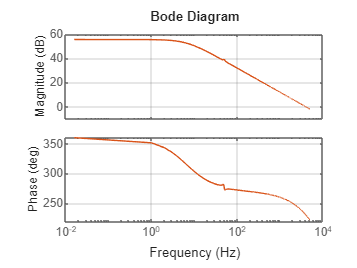

    hold on;
    hd = bodeplot(OL_s,w_range);
    grid on;
    setoptions(hd,'MagUnits','dB','FreqUnits','Hz','FreqScale','log')


    CL_s = feedback(OL_s,1)


CL_s =
 
        -28.18 s^3 + 1.972e06 s^2 + 4.368e07 s + 1.947e11
  --------------------------------------------------------------
  0.001131 s^4 + 51.09 s^3 + 1.977e06 s^2 + 5.156e07 s + 1.95e11
 
Continuous-time transfer function.
Model Properties


    CL_d = feedback(OL_d,1)


CL_d =
 
    0.7113 z^2 - 1.422 z + 0.7108
  ----------------------------------
  z^3 - 2.287 z^2 + 1.574 z - 0.2874
 
Sample time: 2.8571e-05 seconds
Discrete-time transfer function.
Model Properties


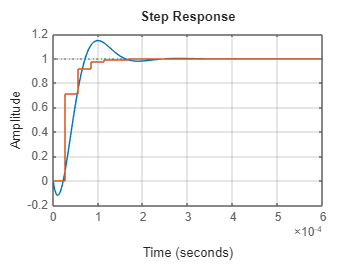

    figure
    step(CL_s);
    hold on;
    step(CL_d)
    grid on;




Current_CL_d = feedback(OL_d,1)


Current_CL_d =
 
    0.7113 z^2 - 1.422 z + 0.7108
  ----------------------------------
  z^3 - 2.287 z^2 + 1.574 z - 0.2874
 
Sample time: 2.8571e-05 seconds
Discrete-time transfer function.
Model Properties


figure
H = bodeplot(CL_s,w_range)

H =   BodePlot with properties:

                 Responses: [1×1 controllib.chart.response.BodeResponse]
           Characteristics: [1×1 controllib.chart.options.CharacteristicsManager]

             FrequencyUnit: "rad/s"
            FrequencyScale: "log"
             MagnitudeUnit: "dB"
            MagnitudeScale: "linear"
                 PhaseUnit: "deg"
          MagnitudeVisible: on
              PhaseVisible: on
      PhaseWrappingEnabled: off
       PhaseWrappingBranch: -180
      PhaseMatchingEnabled: off
    PhaseMatchingFrequency: 0
        PhaseMatchingValue: 0
        MinimumGainEnabled: off
          MinimumGainValue: 0

                   Visible: on
                IOGrouping: "none"
              InputVisible: on
             OutputVisible: on

  Show 

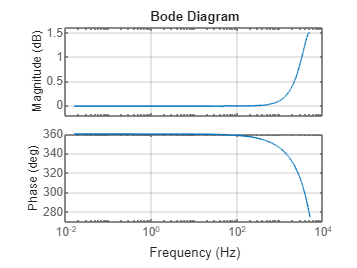

setoptions(H,'MagUnits','dB','FreqUnits','Hz','FreqScale','log')
grid on;

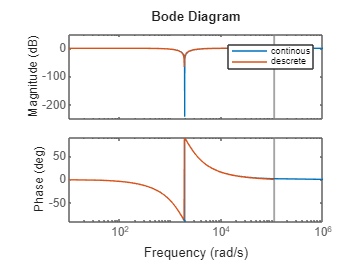

    %Notch filter for DC bus 2nd harmonics removal purpose
    zeta = 0.707;
    wo_notch = 2*pi*acdc.Fac * 6; %6 times the grid frequncy
    notch_s = tf([1, 0, wo_notch^2],[1 2*zeta*wo_notch wo_notch^2]);
    notch_d = c2d(notch_s,acdc.Tvolt_loop);
    [acdc.notch_num,acdc.notch_den] = tfdata(notch_d,'v');
    
    bode(notch_s);
    hold on;
    bode(notch_d);
    legend("continous","descrete");


    %SOGI
    acdc.sogi_k = 0.5;
    acdc.sogi_UL = 500;
    acdc.sogi_LL = -500;


%%%%%%% Voltage loop  gains %%%%%%%%%%%%%%%%%

%plant TF
iL2iDC = 3*acdc.Eff*acdc.Vph_rms/acdc.Vout      %Iline to Idc gain

iL2iDC = 0.8400


RC_s = tf([acdc.Rload],[acdc.C*acdc.Rload 1])   %RC TF


RC_s =
 
     53.33
  ------------
  0.0098 s + 1
 
Continuous-time transfer function.
Model Properties



vbus_plant_s = CL_s * iL2iDC * RC_s;

%controller TF
% kp_v = 5
kp_v =10^(-6.5/20);
ki_v = 50;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


con_s = kp_v + ki_v/s


con_s =
 
  0.4732 s + 50
  -------------
        s
 
Continuous-time transfer function.
Model Properties


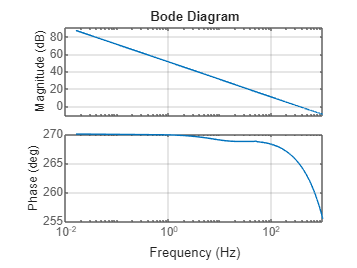

vbus_OL_s = con_s * vbus_plant_s;

    figure
    w_range = linspace(0.1,1000*2*pi,1000);
    h = bodeplot(vbus_OL_s,w_range);
    setoptions(h,'MagUnits','dB','FreqUnits','Hz','FreqScale','log');
    grid on;



    vbus_CL_s = feedback(vbus_OL_s,1)


vbus_CL_s =
 
                 -597.4 s^4 + 4.174e07 s^3 + 5.344e09 s^2 + 4.225e12 s + 4.362e14
  ----------------------------------------------------------------------------------------------
  1.109e-05 s^6 + 0.5018 s^5 + 1.883e04 s^4 + 4.423e07 s^3 + 7.307e09 s^2 + 4.42e12 s + 4.362e14
 
Continuous-time transfer function.
Model


    figure
H = bodeplot(vbus_CL_s,w_range)

H =   BodePlot with properties:

                 Responses: [1×1 controllib.chart.response.BodeResponse]
           Characteristics: [1×1 controllib.chart.options.CharacteristicsManager]

             FrequencyUnit: "rad/s"
            FrequencyScale: "log"
             MagnitudeUnit: "dB"
            MagnitudeScale: "linear"
                 PhaseUnit: "deg"
          MagnitudeVisible: on
              PhaseVisible: on
      PhaseWrappingEnabled: off
       PhaseWrappingBranch: -180
      PhaseMatchingEnabled: off
    PhaseMatchingFrequency: 0
        PhaseMatchingValue: 0
        MinimumGainEnabled: off
          MinimumGainValue: 0

                   Visible: on
                IOGrouping: "none"
              InputVisible: on
             OutputVisible: on

  Show 

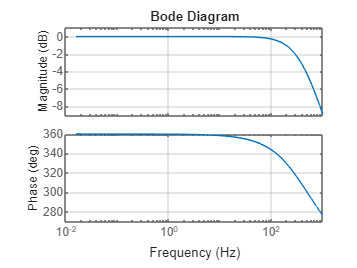

setoptions(H,'MagUnits','dB','FreqUnits','Hz','FreqScale','log')
grid on;


    %Unbalance

    if(power_base_control == 0)
        acdc.vdc_kp = 0.5 *(1/70000)/acdc.Tvolt_loop;
        acdc.vdc_ki = 100 *(1/70000)/acdc.Tvolt_loop;

        acdc.vdc_con_max = acdc.Igrid_ph_pk;
        acdc.vdc_con_min = 0;

            acdc.vdc_kp = kp_v;
    acdc.vdc_ki = ki_v;
     
    else

        acdc.vdc_kp = 0.5*400 *(1/70000)/acdc.Tvolt_loop
        acdc.vdc_ki = 100*400 *(1/70000)/acdc.Tvolt_loop

        acdc.vdc_con_max =  acdc.Pin_max;
        acdc.vdc_con_min = 0;

        acdc.vdc_kp = kp_v *487
        acdc.vdc_ki = ki_v * 487

    end

acdc = struct with fields:
              Pout: 12000
        Vac_ll_rms: 400
           Vph_rms: 230.9401
               Fac: 50
               Wac: 314.1593
               Tac: 0.0200
              Vout: 800
              Iout: 15
               Eff: 0.9700
                Fs: 70000
               Tsw: 1.4286e-05
         Tcur_loop: 2.8571e-05
        Tvolt_loop: 2.8571e-05
           Pin_max: 1.8557e+04
                va: 230.9401
                vb: 230.9401
                vc: 230.9401
             va_ph: 0
             vb_ph: -120
             vc_ph: 120
             va_pk: 326.5986
             vb_pk: 326.5986
             vc_pk: 326.5986
         va_ph_rad: 0
         vb_ph_rad: -2.0944
         vc_ph_rad: 2.0944
         va_pk_3rd: 0
         vb_pk_3rd: 0
         vc_pk_3rd: 0
         va_pk_5th: 0
         vb_pk_5th: 0
         vc_pk_5th: 0
               Pin: 1.2371e+04
       Igrid_ph_pk: 25.2525
        cur_ripple: 1.2626
                 L: 0.0011
             L_ESR: 0.04

acdc = struct with fields:
              Pout: 12000
        Vac_ll_rms: 400
           Vph_rms: 230.9401
               Fac: 50
               Wac: 314.1593
               Tac: 0.0200
              Vout: 800
              Iout: 15
               Eff: 0.9700
                Fs: 70000
               Tsw: 1.4286e-05
         Tcur_loop: 2.8571e-05
        Tvolt_loop: 2.8571e-05
           Pin_max: 1.8557e+04
                va: 230.9401
                vb: 230.9401
                vc: 230.9401
             va_ph: 0
             vb_ph: -120
             vc_ph: 120
             va_pk: 326.5986
             vb_pk: 326.5986
             vc_pk: 326.5986
         va_ph_rad: 0
         vb_ph_rad: -2.0944
         vc_ph_rad: 2.0944
         va_pk_3rd: 0
         vb_pk_3rd: 0
         vc_pk_3rd: 0
         va_pk_5th: 0
         vb_pk_5th: 0
         vc_pk_5th: 0
               Pin: 1.2371e+04
       Igrid_ph_pk: 25.2525
        cur_ripple: 1.2626
                 L: 0.0011
             L_ESR: 0.04

acdc = struct with fields:
              Pout: 12000
        Vac_ll_rms: 400
           Vph_rms: 230.9401
               Fac: 50
               Wac: 314.1593
               Tac: 0.0200
              Vout: 800
              Iout: 15
               Eff: 0.9700
                Fs: 70000
               Tsw: 1.4286e-05
         Tcur_loop: 2.8571e-05
        Tvolt_loop: 2.8571e-05
           Pin_max: 1.8557e+04
                va: 230.9401
                vb: 230.9401
                vc: 230.9401
             va_ph: 0
             vb_ph: -120
             vc_ph: 120
             va_pk: 326.5986
             vb_pk: 326.5986
             vc_pk: 326.5986
         va_ph_rad: 0
         vb_ph_rad: -2.0944
         vc_ph_rad: 2.0944
         va_pk_3rd: 0
         vb_pk_3rd: 0
         vc_pk_3rd: 0
         va_pk_5th: 0
         vb_pk_5th: 0
         vc_pk_5th: 0
               Pin: 1.2371e+04
       Igrid_ph_pk: 25.2525
        cur_ripple: 1.2626
                 L: 0.0011
             L_ESR: 0.04

acdc = struct with fields:
              Pout: 12000
        Vac_ll_rms: 400
           Vph_rms: 230.9401
               Fac: 50
               Wac: 314.1593
               Tac: 0.0200
              Vout: 800
              Iout: 15
               Eff: 0.9700
                Fs: 70000
               Tsw: 1.4286e-05
         Tcur_loop: 2.8571e-05
        Tvolt_loop: 2.8571e-05
           Pin_max: 1.8557e+04
                va: 230.9401
                vb: 230.9401
                vc: 230.9401
             va_ph: 0
             vb_ph: -120
             vc_ph: 120
             va_pk: 326.5986
             vb_pk: 326.5986
             vc_pk: 326.5986
         va_ph_rad: 0
         vb_ph_rad: -2.0944
         vc_ph_rad: 2.0944
         va_pk_3rd: 0
         vb_pk_3rd: 0
         vc_pk_3rd: 0
         va_pk_5th: 0
         vb_pk_5th: 0
         vc_pk_5th: 0
               Pin: 1.2371e+04
       Igrid_ph_pk: 25.2525
        cur_ripple: 1.2626
                 L: 0.0011
             L_ESR: 0.04

% DC- DC converter design

%inductor design
V_max_out_dcdc = V_out_dcdc*1.2 % 20% margin

V_max_out_dcdc = 115.2000

transformer_turn_ratio = (V_max_out_dcdc)/V_in_dcdc     %max output volt/input volt

transformer_turn_ratio = 0.1536

nominal_duty = V_out_dcdc/V_max_out_dcdc * 1/2          % nominal /max output voltage

nominal_duty = 0.4167

V_Lo = V_in_dcdc * transformer_turn_ratio - V_out_dcdc  %voltage across output inductor

V_Lo = 19.2000


I_out_nom = 125;                         %(max+min)/2
I_out_ripple = I_out_nom * 0.02;  %+/- 1% =  2%
Lo = V_Lo*nominal_duty*Tswitching/(I_out_ripple)

Lo = 6.4000e-05



%capacitor design
V_out_ripple = V_out_dcdc * 0.01;  %+/- 0.5% =  1%

Co = I_out_ripple*nominal_duty*Tswitching/V_out_ripple

Co = 2.1701e-05

%Controller parameters
Volt_loop_upper_limit = Imax_out;
Cur_loop_upper_limit = 180;

PWM_strategy = 0

PWM_strategy = 0

% sim('Vienna_3ph_universal.slx',0.1);

%Plot
time =  out.volt_vur_load.Time(:,1);

Unable to resolve the name 'out.volt_vur_load.Time'.

skip_data = 1600;
Tss = time(4) - time(3)
Skip_sec = 0.06;
skip_data = int32(Skip_sec/Tss);
ia_out = out.volt_vur_load.Data(skip_data:end,1);
Vbus = out.volt_vur_load.Data(skip_data:end,4);
Vbus_ref = out.volt_vur_load.Data(skip_data:end,5);
Load = out.volt_vur_load.Data(skip_data:end,6);
va_out = out.volt_vur_load.Data(skip_data:end,7);

t = time(skip_data:end);
figure

subplot(3,1,1)
plot(t,acdc.Vref^2./Load);
grid on;
legend(["Load"]);
ylabel("Load (watts)");
xlabel("time(sec)")

subplot(3,1,2)
plot(t,ia_out);
hold on
plot(t,va_out/10);
grid on;
legend(["Igrid","Vgrid/10"]);
ylabel("Current(A)");
xlabel("time(sec)")

subplot(3,1,3)
plot(t,Vbus);
hold on
plot(t,Vbus_ref);
grid on;
legend(["Vbus","Vbus__ref"])
ylabel("Voltage(V)");
xlabel("time(sec)")
% xlim([0.04,0.016]);


figure

Skip_sec = 0.08;
skip_data = int32(Skip_sec/Tss);
P_in = out.pow_eff.Data(skip_data:end,1);
P_out = out.pow_eff.Data(skip_data:end,2);
Eff = out.pow_eff.Data(skip_data:end,3);
PF = out.pow_eff.Data(skip_data:end,4);
THD = out.pow_eff.Data(skip_data:end,5);
t = time(skip_data:end);

subplot(3,1,1);
plot(t,P_in);
hold on
plot(t,P_out);
grid on;
legend(["Input Power","Output Power"])
ylabel("Power(Watts)");
xlabel("time(sec)")

subplot(3,1,2);
plot(t,Eff);
% legend(["Efficiency"]);
% hold on;
% plot(t,PF);
grid on;
legend(["Efficiency"]);
ylabel("%");
xlabel("time(sec)")

subplot(3,1,3);
% plot(t,Eff);
% legend(["Efficiency"]);
% hold on;
plot(t,PF);
grid on;
legend(["Power factor"]);
ylabel("PF");
xlabel("time(sec)")
% 
% subplot(3,1,3);
% plot(t,THD);
% grid on;
% legend(["Current THD"]);

% t = 0:0.001:5-0.001;
% x = 10*sin(2*pi*50*t);
[mag_one_sided, mag_two_sided, f_one_sided, f_two_sided] = signal_FFT(ia_out,Tss);

figure
plot(f_one_sided,abs(mag_one_sided));
grid on;

%THD
Skip_sec = 0.08;
skip_data = int32(Skip_sec/Tss);
ia_out = out.volt_vur_load.Data(skip_data:end,1);
Vbus = out.volt_vur_load.Data(skip_data:end,4);
% ia_out = out.volt_vur_load.Data(skip_data:end,7);
L = length(ia_out);
N = 50;

ia_long = [];

for i=1:N

    ia_long = [ia_long; ia_out];
end

T = L*Tss;
t = 0:Tss:T*N-Tss;

figure
subplot(3,1,2)
plot(Vbus);
grid on;
ylabel("Current(A)");
xlabel("time(sec)");

[outputSignal, outputSignal_for_ifft,frequency_range,frequency_range_ifft] = signal_FFT(ia_long,Tss);
mag = abs(outputSignal);
f_max = frequency_range(end)
index_h1 = find(mag == max(mag))
f_h1 = frequency_range(index_h1)
mag_h1 = mag(index_h1)
max_har_f = 25*f_h1;



har_mag = [mag_h1];
har_freq = [f_h1];
har = [1];

for i=3:2:25  %odd harmonics

f1 = f_h1*i - 0.1*i;
f2 = f_h1*i + 0.1*i;

indx1 = find(frequency_range>=f1 &  frequency_range<=f2);

har_freq = [har_freq f_h1*i];
har_mag = [har_mag max(mag(indx1))];
har = [har i];

end

figure
bar(har,har_mag);
grid on

THD = sqrt(sum(har_mag(2:end).^2))/har_mag(1)*100

Vbus_rippl_per = (max(Vbus)- min(Vbus))/mean(Vbus) * 100

Unbalance
harmonics
power_base_control %0: current based control, 1:power based control
vdc_fbk_filter

parent_dir = pwd;
dir1 = strcat(parent_dir,'\C_Code');
cd(dir1);
headerfiles = strcat(pwd,'\generic\GenericBlocks.h');
headerfiles = {headerfiles, 'Pll.h','VbusController.h','CurRefGen.h','CurController.h'};
Simulink.importExternalCTypes(headerfiles);



% def = legacy_code('initialize');
% 
% def.SrcPaths = {'generic'};
% def.IncPaths = {'generic'};
% 
% def.SourceFiles = {'Vienna.c','GenericBlocks.c','Pll.c','VbusController.c','CurRefGen.c','CurController.c'};
% def.HeaderFiles = {'Vienna.h','Pll.h'};
% def.InitializeConditionsFcnSpec = ['vienna_initialize()'];
% 
% def.SFunctionName = 'sfun_pll';
% def.OutputFcnSpec = ['sim_pll_calc(ABC_TYPE u1[1], PLL_OUT_TYPE y1[1])'];
% legacy_code('generate_for_sim',def);
% 
% def.SFunctionName = 'sfun_vbus_con';
% def.OutputFcnSpec = ['sim_VbusController_calc(VBUSCONTROLLER_IN_TYPE u1[1], VBUSCONTROLLER_OUT_TYPE y1[1])'];
% legacy_code('generate_for_sim',def);
% 
% def.SFunctionName = 'sfun_cur_ref_gen';
% def.OutputFcnSpec = ['sim_CurRefGen_calc(CURREFGEN_IN_TYPE u1[1], CURREFGEN_OUT_TYPE y1[1])'];
% legacy_code('generate_for_sim',def);
% 
% 
% def.SFunctionName = 'sfun_cur_con';
% def.OutputFcnSpec = ['sim_CurController_calc(CURCONTROLLER_IN_TYPE u1[1], CURCONTROLLER_OUT_TYPE y1[1])'];
% legacy_code('generate_for_sim',def);
% 
% mexDir = strcat(pwd,'\mex');
% %delete old sfun files 
% path2sfunfiles = strcat(mexDir,'\sfun_*.*');
% delete(path2sfunfiles);
% 
% %move new sfun files to mex folder
% files = dir('sfun_*.*');
% for i = 1:size(files, 1)
%     movefile([files(i).name], mexDir);
% end
% 
% dir1 = strcat(parent_dir,'\Simulation');
% cd(dir1);
% 
% 

% mstruct = Simulink.Bus.createMATLABStruct("CURREFGEN_IN_TYPE");